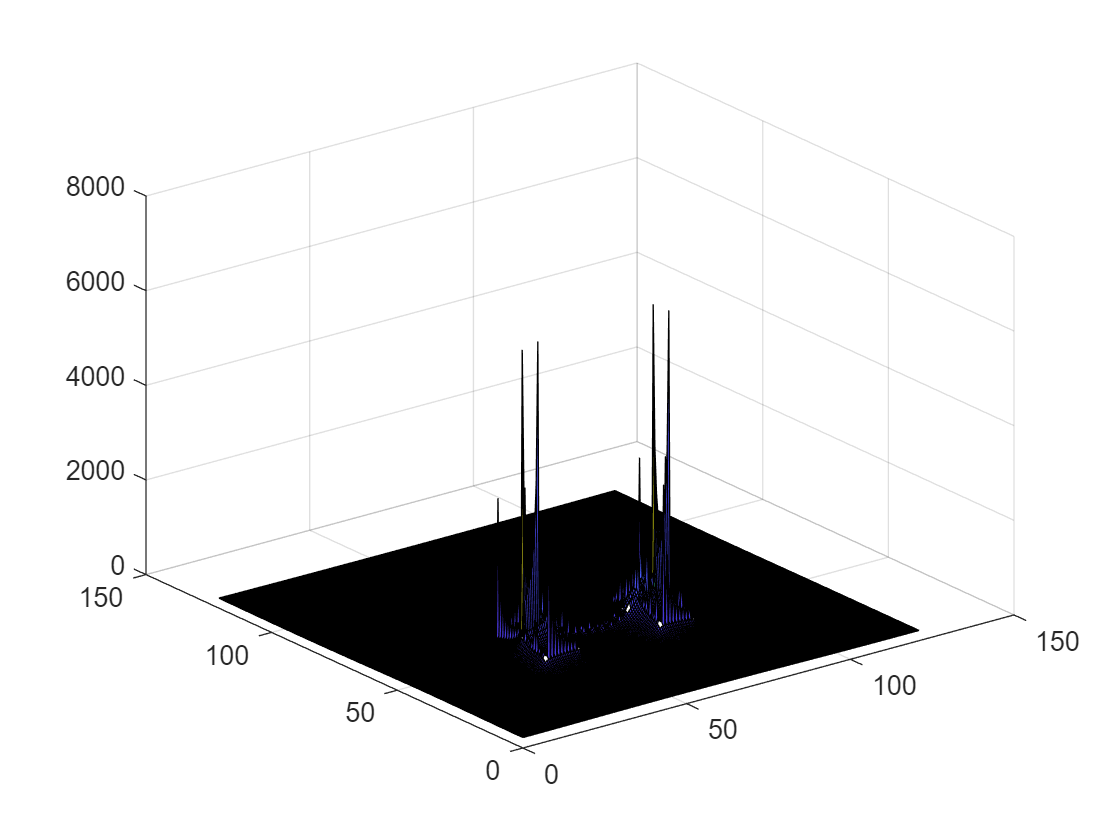

clear all
clf 
%% 定义函数输入
r=3;%最小转弯半径
Stepsize=0.01;%路径的生成间隔

sure=1;%保证安全的预留距离
% R=10+sure;


mapsize=100;
num=0;%%%%随机障碍物数量
R=[20,20];%%%障碍物半径范围;
num_obs_nocircle=5;
num_steps=100;%%%%边界上几个点
% Start_Point = [100,0,-pi/6];
% End_Point = [200,200,-pi/2];%[x,y,角度]

% Start_Point = [round(rand(1,2)*mapsize),-pi+rand(1)*2*pi];
% End_Point = [round(rand(1,2)*mapsize),-pi+rand(1)*2*pi];%[x,y,角度]

Start_Point = [48,5+30,-pi+rand(1)*2*pi];
% Start_Point = [0,0,-pi];
End_Point = [55,18+30,-pi+rand(1)*2*pi];%[x,y,角度]


Start_Point = [48,5+30,0.9561];
% Start_Point = [0,0,-pi];
End_Point = [55,18+30,-3*pi/4];%[x,y,角度]

obs_no_circle{1}=[0,10;
        5,10;        
        10,12;
        10,20;
        0,20;
        0,10];
obs_no_circle{2}=[0,0;
        10,0;
        10,8;
        5,9;        
        0,9
        0,0];
obs_no_circle{3}=[
        
        25,10;
        25,20;
        15,20;
        15,12;
        20,10;
        25,10];
obs_no_circle{4}=[15,0;
        25,0;
        25,9;
        20,9;
        15,8;
        15,0];

obs_no_circle{5}=[12+20,9;
                       19+20,10;
                       12+20,11;
                       6,10;
                       12+20,9];
obs_no_circle{3}(:,1)=obs_no_circle{3}(:,1)+20;
obs_no_circle{4}(:,1)=obs_no_circle{4}(:,1)+20;
outline_all=[];
for i=1:length(obs_no_circle)
% plot(obs_no_circle{i}(:,1),obs_no_circle{i}(:,2),'k-');hold on;
obs_no_circle{i}=obs_no_circle{i}+30;
for k=1:length(obs_no_circle{i}(:,1))-1
    x_interp = linspace(obs_no_circle{i}(k,1), obs_no_circle{i}(k+1,1), num_steps);
    y_interp = linspace(obs_no_circle{i}(k,2), obs_no_circle{i}(k+1,2), num_steps);
    outline=[x_interp;y_interp]';
    outline=[outline,ones(length(outline(:,1)),1)*i];
    outline_all=[outline_all;outline];
end

end
obs_no_circle_in=obs_no_circle;

% Start_Point = [120,120,-pi+rand(1)*2*pi];
% End_Point = [200,200,-pi+rand(1)*2*pi];%[x,y,角度]
% 
% outline_all=[];
% center=[            110,180;
%                   90,170;  130,175; 
%                70,165;        140,160;
%              50,155;             150,145;
%             40,145;
%           30,130;                  160,130;
%         20,115;                     
%       10,100;                       160,110;
%                                    150,95;
%                                   140,80;
%                                  130,65;
% 
% 
%          ];
% 
% for i=1:length(center(:,1))
%     [outline,vertex,expandedPolygon]=obtain_obs_nocircle_hand(center(i,:)',mapsize,R,num_steps,Start_Point,End_Point,sure);
%     if ~isempty(outline)
%         outline=[outline,ones(length(outline(:,1)),1)*i];
%         outline_all=[outline_all;outline];
%         obs_no_circle{i}=expandedPolygon;
%         obs_no_circle_in{i}=vertex;
%     end
% end






% [outline_all,obs_no_circle,obs_no_circle_in]=obtain_obs_no_circle_all(num_obs_nocircle,mapsize,R,num_steps,Start_Point,End_Point,sure);

% total_field=obtian_field(mapsize+R(2)+sure,End_Point,outline_all,k_att,k_rep,r_search);
% [obs,obs_no_circle,obs_no_circle_in,outline_all]=obtain_map(num,mapsize,Start_Point, End_Point,R,r,obs_no_circle,obs_no_circle_in,outline_all);%[x,y,障碍物的安全半径R]


r_search=15;%%探测半径
k_att=1.5;%计算引力需要的增益系数
k_rep=30;%计算斥力的增益系数，都是自己设定的。


% load("trap_ao3.mat") 
total_field=obtian_field(mapsize+R(2)+sure,End_Point,outline_all,k_att,k_rep,r_search);

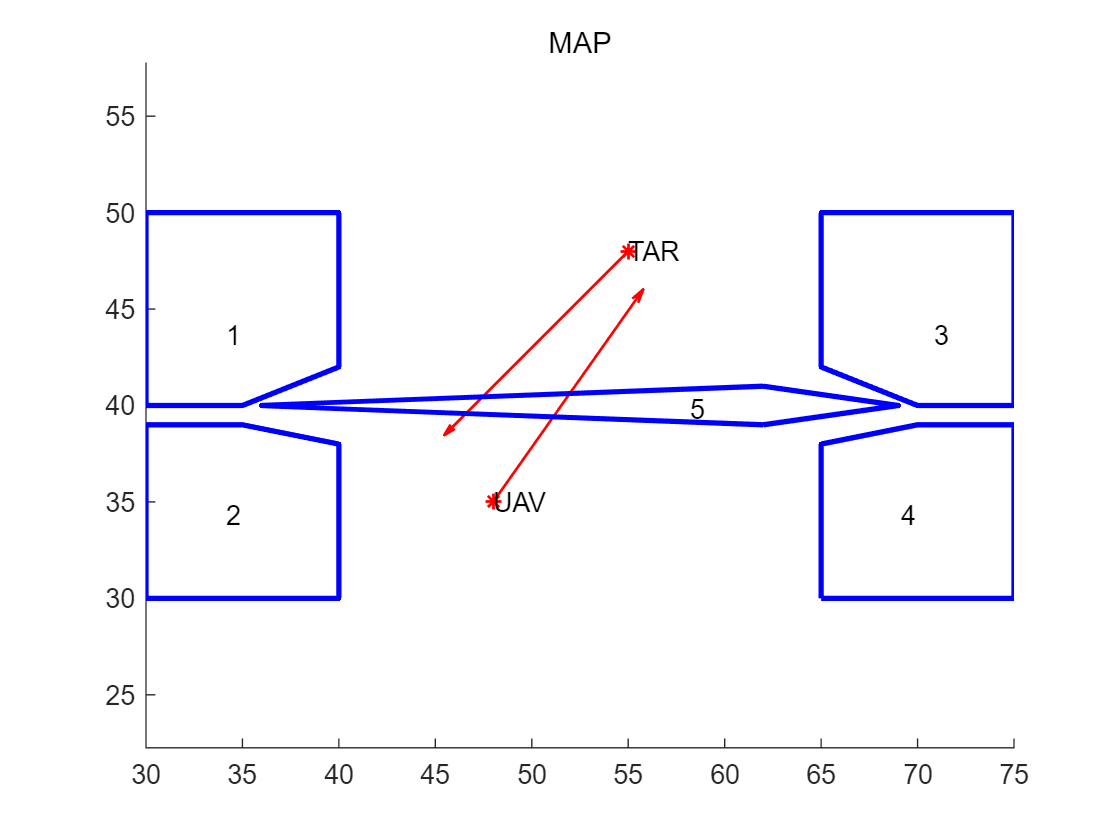

Draw_map(Start_Point,End_Point,[],sure,obs_no_circle_in,[]);%绘制地图


tic
[final_path,open,close]=A_dubins_nocircle_trap(Start_Point,End_Point,[],sure,r,obs_no_circle,obs_no_circle,outline_all,Stepsize,total_field);

from           -1                  avoid  5
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
open is empty!Mayday!even in begin!!
from           -1                  avoid  1
2
2 succed 1
directly find 1-2 safe
2 succed 2
需要插入点
from           -1                  avoid  2
2
type 2
2 succed 1
directly find 1-2 safe
2 succed 2
directly find 1-2 safe
from           -1                  avoid  3
3
3 succed 1
directly find 1-2 safe
3 succed 2
directly find 1-2 safe
from           -1                  avoid  4
3
3 succed 1
directly find 1-2 safe
3 succed 2
directly find 1-2 safe
from           -1                  avoid  5
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           1                  avoid  5
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           4                  avoid  5
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           1                  avoid  5
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           1    

toc

历时 6.095898 秒。


length(close)+length(open)

ans = 15

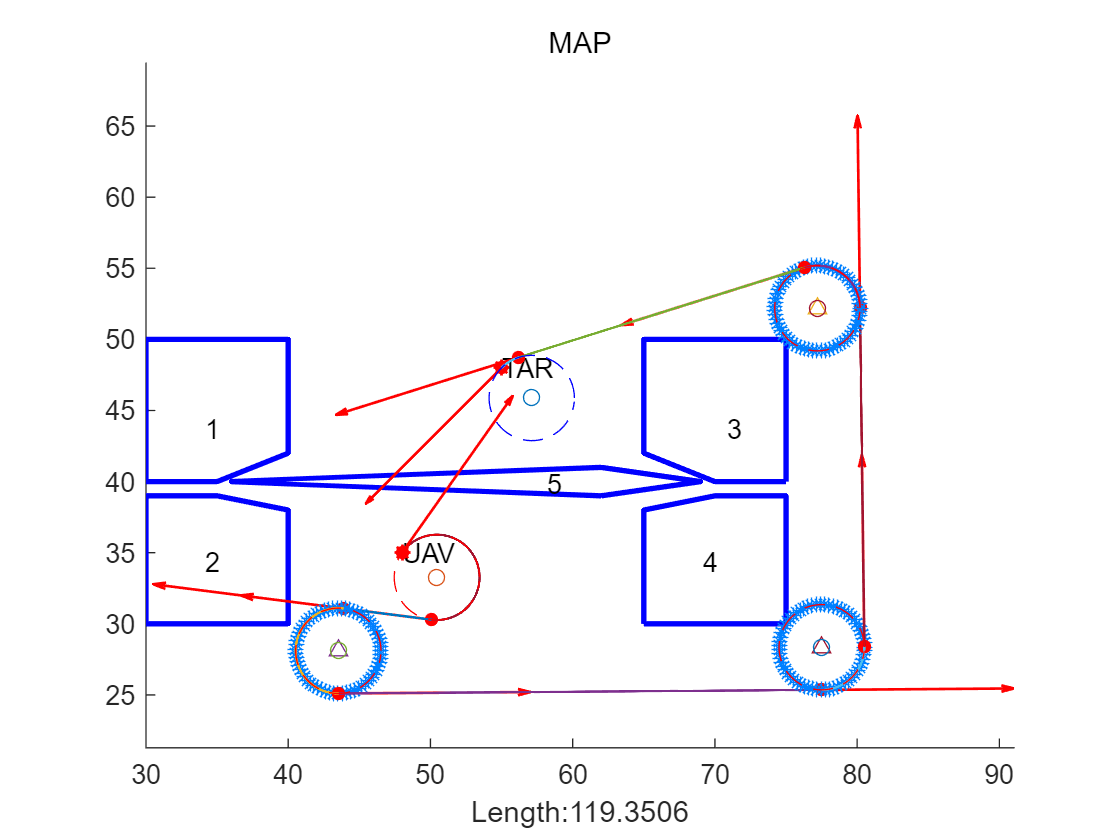

figure
Draw_map(Start_Point,End_Point,[],sure,obs_no_circle_in,[]);%绘制地图
Draw_pathA_no_circle(final_path);

hold off

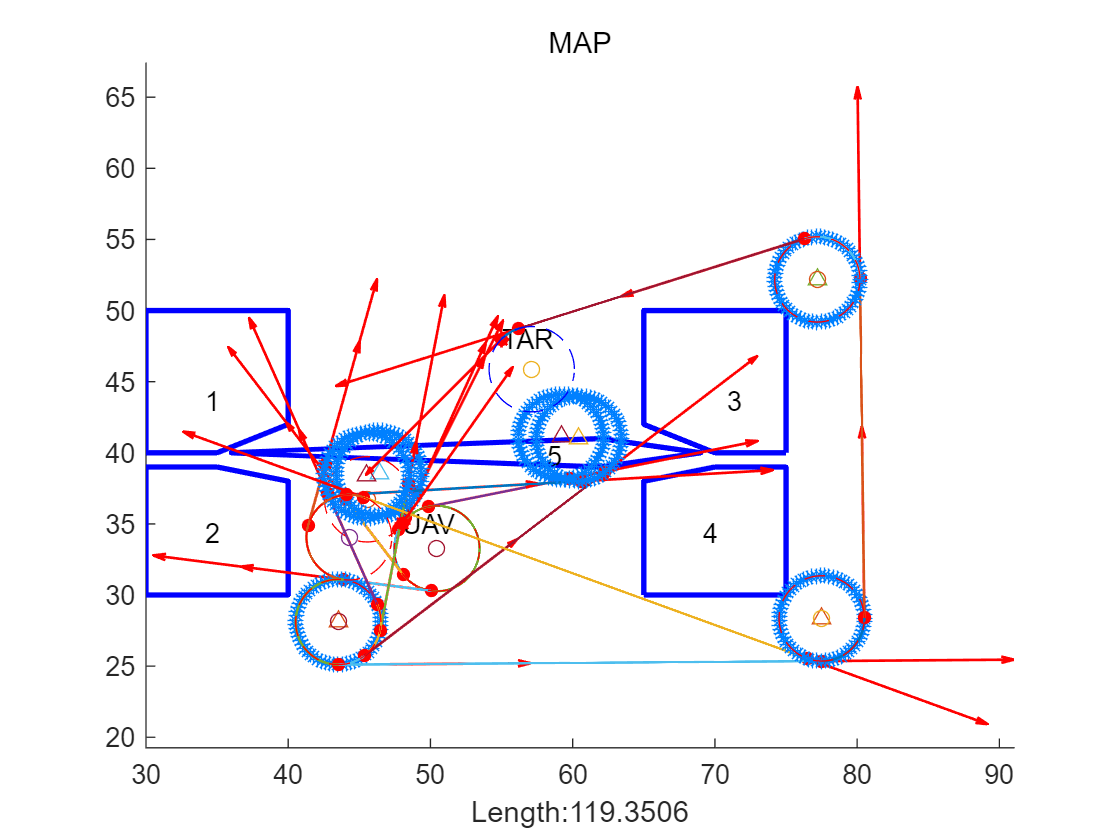

Index exceeds the number of array elements. Index must not exceed 0.

出错 Draw_pathA_no_circle_open_close (第 67 行)
plot(close{1}.point(1,1),close{1}.point(2,1),'.','MarkerSize',15,'MarkerFaceColor','r','MarkerEdgeColor','r');

figure

Draw_map(Start_Point,End_Point,[],sure,obs_no_circle_in,[]);%绘制地图
Draw_pathA_no_circle(close);                    
Draw_pathA_no_circle_open_close(open);

hold off





tic
[final_path_nofather,open_nofather,close_nofather]=A_dubins_nocircle_no_father(Start_Point,End_Point,[],sure,r,obs_no_circle,obs_no_circle,outline_all,Stepsize,total_field);

from           -1                  avoid  5
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
open is empty!Mayday!even in begin!!
from           -1                  avoid  1
2
2 succed 1
directly find 1-2 safe
2 succed 2
需要插入点
from           -1                  avoid  2
2
type 2
2 succed 1
directly find 1-2 safe
2 succed 2
directly find 1-2 safe
from           -1                  avoid  3
3
3 succed 1
directly find 1-2 safe
3 succed 2
directly find 1-2 safe
from           -1                  avoid  4
3
3 succed 1
directly find 1-2 safe
3 succed 2
directly find 1-2 safe
from           -1                  avoid  5
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           1                  avoid  5
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           4                  avoid  5
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           1                  avoid  5
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           1    

toc

历时 5.629242 秒。


length(close_nofather)+length(open_nofather)

ans = 17

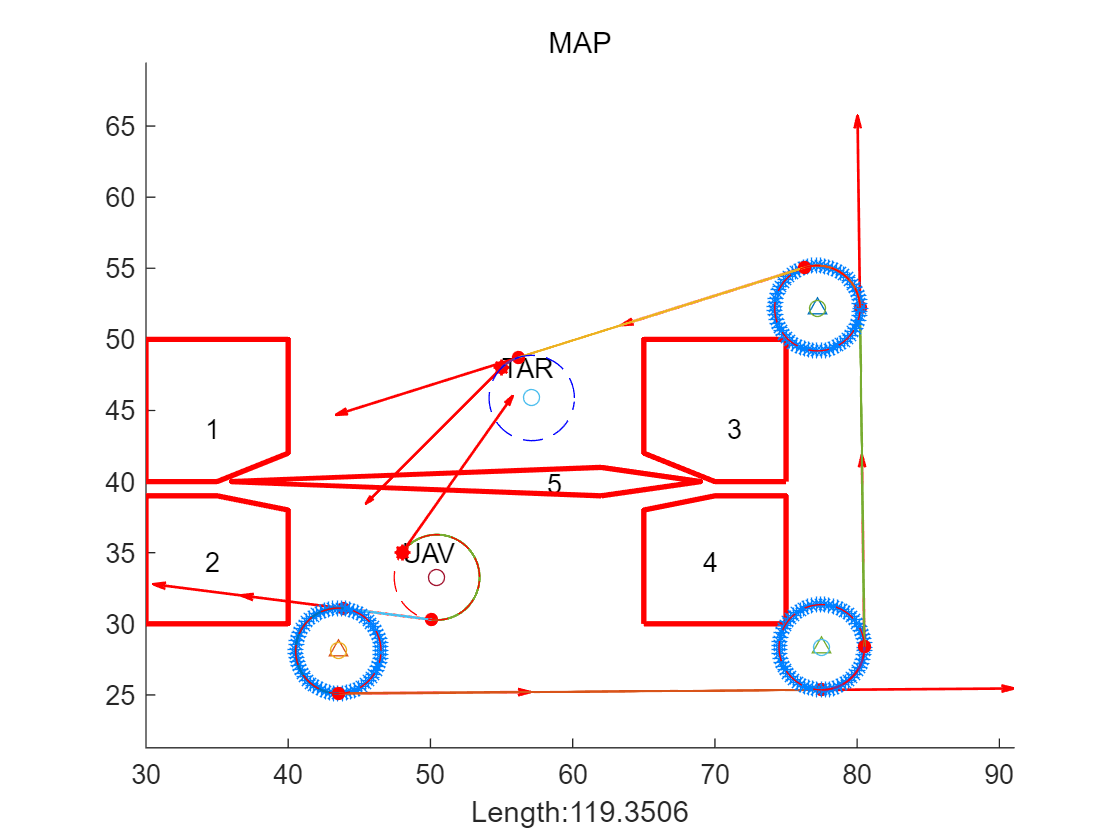

figure
Draw_map(Start_Point,End_Point,[],sure,obs_no_circle_in,obs_no_circle);%绘制地图
Draw_pathA_no_circle(final_path_nofather);

hold off

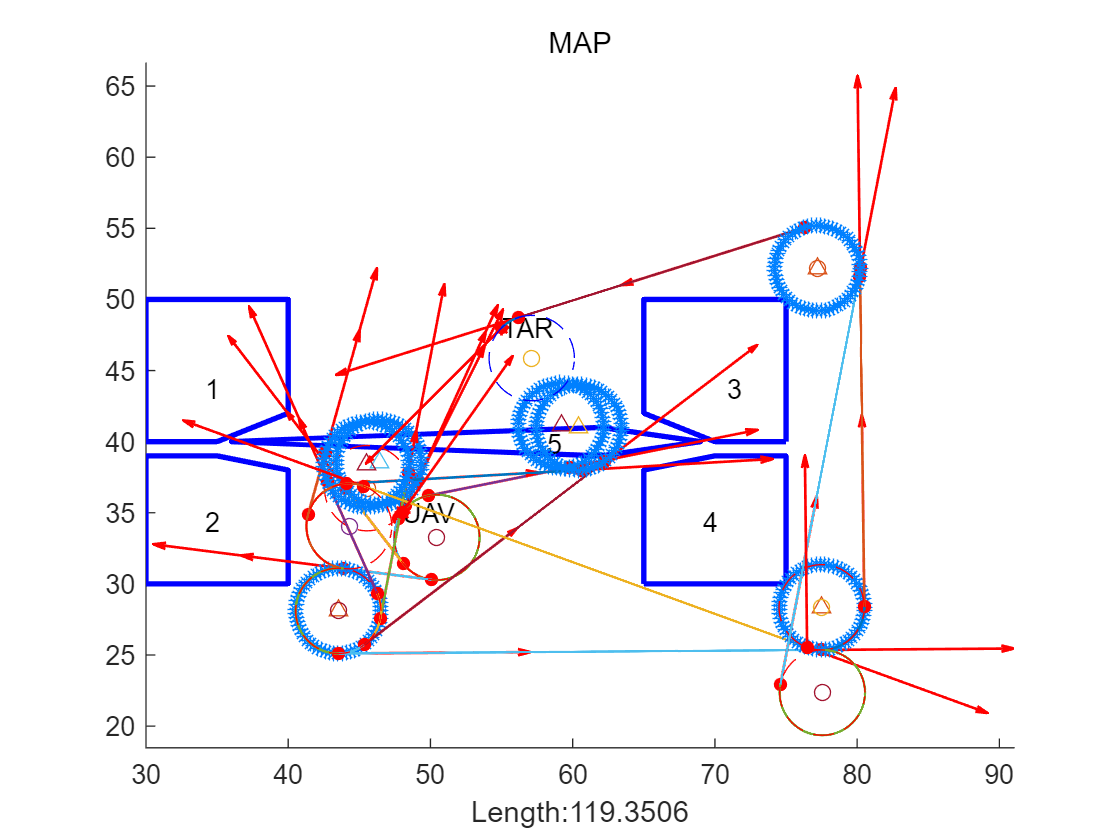

figure

Draw_map(Start_Point,End_Point,[],sure,obs_no_circle_in,[]);%绘制地图
Draw_pathA_no_circle(close_nofather);                    
Draw_pathA_no_circle_open_close(open_nofather);
hold off

tic
[final_path_none,open_none,close_none]=A_dubins_nocircle_none(Start_Point,End_Point,[],sure,r,obs_no_circle,obs_no_circle,outline_all,Stepsize,total_field);
toc
length(close_none)+length(open_none)
figure
Draw_map(Start_Point,End_Point,[],sure,obs_no_circle_in,obs_no_circle);%绘制地图
Draw_pathA_no_circle(final_path_none);

hold off
figure

Draw_map(Start_Point,End_Point,[],sure,obs_no_circle_in,obs_no_circle);%绘制地图
Draw_pathA_no_circle(close_none);                    
Draw_pathA_no_circle_open_close(open_none);
hold off

